# Sample 9-6

## 離散ウェーブレット変換

２変量離散ウェーブレット変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Bivariate discrete wavelet transform

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all
import msip.download_img
download_img()

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## 画像の読込

(Read image)

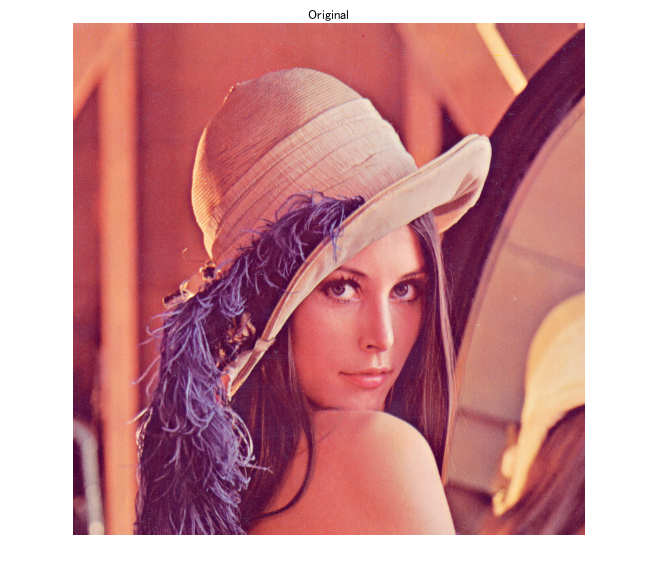

u = im2double(imread('./data/lena.png'));
figure(1)
imshow(u)
title('Original')

### 画像の9/7-変換と逆変換

(The 9/7-transform and its inverse of an image)

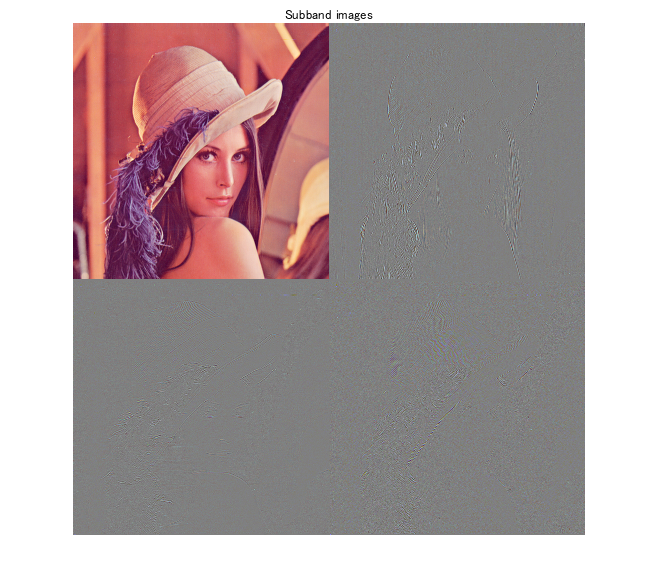

% Foreard 9/7-transform
[subLL,subHL,subLH,subHH] = imtrans97(u);

% Show subband images
picturesSub = [ subLL    subHL+.5;
                subLH+.5 subHH+.5 ];
figure(2)
imshow(picturesSub)
title('Subband pictures')
title('Subband images')

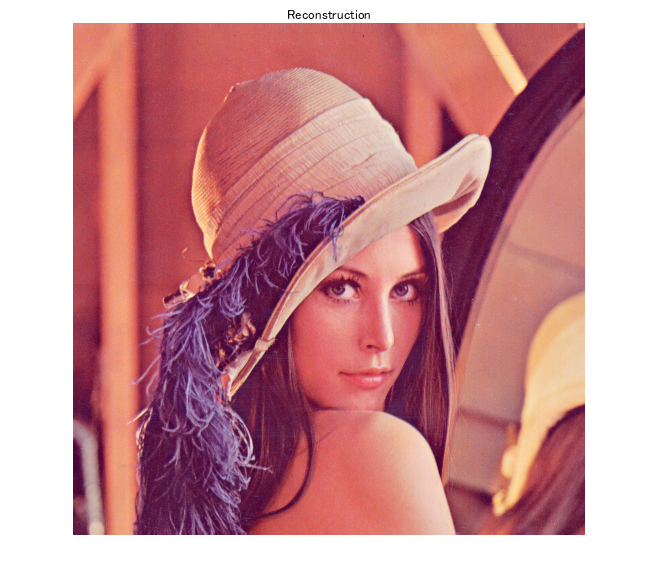

% Inverse 9/7-transform
v = imitrans97(subLL,subHL,subLH,subHH);

% Show reconstructed picture
figure(3)
imshow(v)
title('Reconstruction')

### 画像の9/7-DWTと逆変換

(The 9/7-DWT and its inverse of an image)

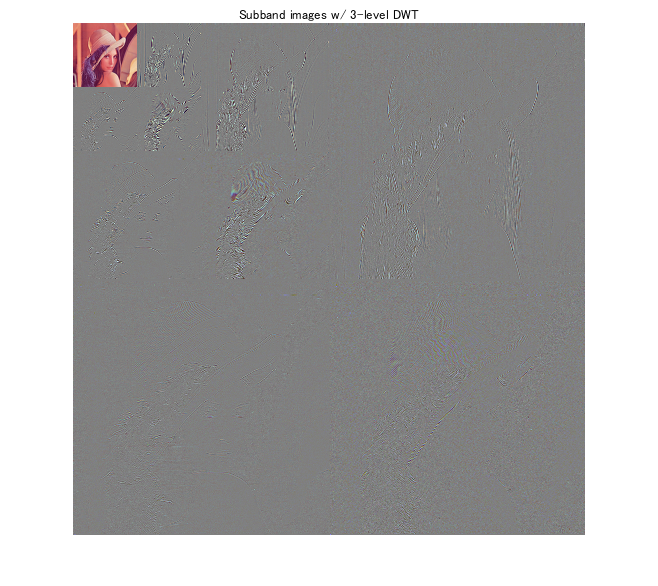

% 3-Level 9/7 DWT
[subLL2,subHL2,subLH2,subHH2] = imtrans97(u);
[subLL1,subHL1,subLH1,subHH1] = imtrans97(subLL2);
[subLL0,subHL0,subLH0,subHH0] = imtrans97(subLL1);

% 
subband0 = [subLL0 subHL0+.5 ; 
    subLH0+.5 subHH0+.5];
subband1 = [subband0 subHL1+.5 ; 
    subLH1+.5 subHH1+.5];
subband2 = [ subband1 subHL2+.5;
    subLH2+.5 subHH2+.5 ];
figure(4)
imshow(subband2)
title('Subband images w/ 3-level DWT')

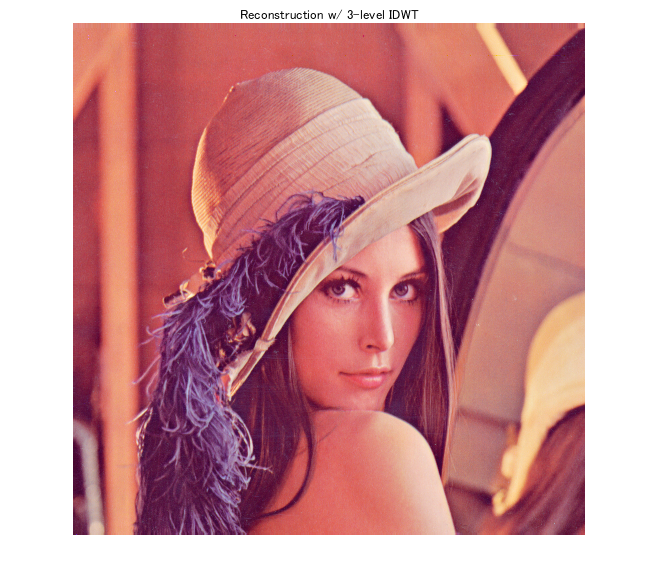


% 3-Level 9/7-IDWT
subLL1 = imitrans97(subLL0,subHL0,subLH0,subHH0);
subLL2 = imitrans97(subLL1,subHL1,subLH1,subHH1);
w = imitrans97(subLL2,subHL2,subLH2,subHH2);

% Reconstruction
figure(5)
imshow(w)
title('Reconstruction w/ 3-level IDWT')

% PSNR evaluation
psnr(im2uint8(u),im2uint8(w))

ans = Inf

### 画像近似

(Image approximation)

3-level 9/7-DWT による近似 (Approximation through the 3-level 9/7-DWT)

% 3-Level 9/7-IDWT
subLL1 = imitrans97(subLL0 ,0*subHL0, 0*subLH0, 0*subHH0);
subLL2 = imitrans97(subLL1, 0*subHL1, 0*subLH1, 0*subHH1);
r = imitrans97(subLL2, 0*subHL2, 0*subLH2, 0*subHH2);


8×8 DCT による近似 (Approximation through the 8×8 DCT)

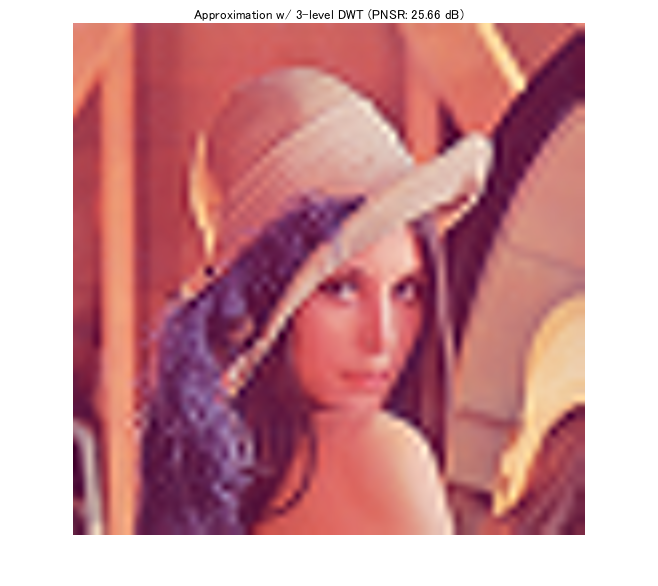

mask = zeros(8);
mask(1) = 1;
[c1,c2,c3] = imsplit(u);
fun = @(x) idct2(mask.*dct2(x.data));
y1 = blockproc(c1,[8 8],fun);
y2 = blockproc(c2,[8 8],fun);
y3 = blockproc(c3,[8 8],fun);
y = cat(3,y1,y2,y3);


% Reconstruction
figure(6)
imshow(r)
title(['Approximation w/ 3-level DWT (PNSR: ' num2str(psnr(im2uint8(u),im2uint8(r))) ' dB)'])

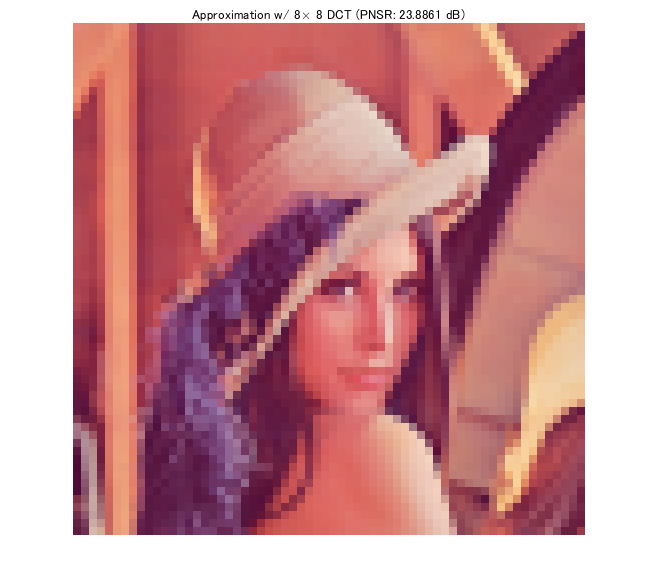

figure(7)
imshow(y)
title(['Approximation w/ 8\times 8 DCT (PNSR: ' num2str(psnr(im2uint8(u),im2uint8(y))) ' dB)'])

### 画像圧縮

(Image compression)

% JPEG w/ DCT
imwrite(u,'lena.jpg','Quality',10)
jpginfo = imfinfo('lena.jpg')

jpginfo = フィールドをもつ struct :
           Filename: 'D:\Workspace\GitHub\AtipWork\lena.jpg'
        FileModDate: '24-Jun-2020 01:19:32'
           FileSize: 9558
             Format: 'jpg'
      FormatVersion: ''
              Width: 512
             Height: 512
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}



% JPEG2000 w/ 9/7-DWT
imwrite(u,'lena.jp2','CompressionRatio',80.7)
jp2info = imfinfo('lena.jp2')

jp2info = フィールドをもつ struct :
                      Filename: 'D:\Workspace\GitHub\AtipWork\lena.jp2'
                   FileModDate: '24-Jun-2020 01:19:32'
                      FileSize: 9504
                        Format: 'JP2'
                 FormatVersion: []
                         Width: 512
                        Height: 512
                      BitDepth: 24
                     ColorType: 'truecolor'
                 BitsPerSample: [8 8 8]
                 CodeBlockDims: [64 64]
          CodestreamComponents: 3
             CodestreamProfile: 'PROFILE2'
                    ColorSpace: 'sRGB'
                      Comments: {}
             ChannelDefinition: {3×3 cell}
            ImageStartLocation: [1 1]
                 NumberOfTiles: 1
              ProgressionOrder: 'LRCP: Layer, Resolution, Component, Position'
                 QualityLayers: 1
                      TileSize: [512 512]
    WaveletDecompositionLevels: 5
                 WaveletKernel: '9x7'
           

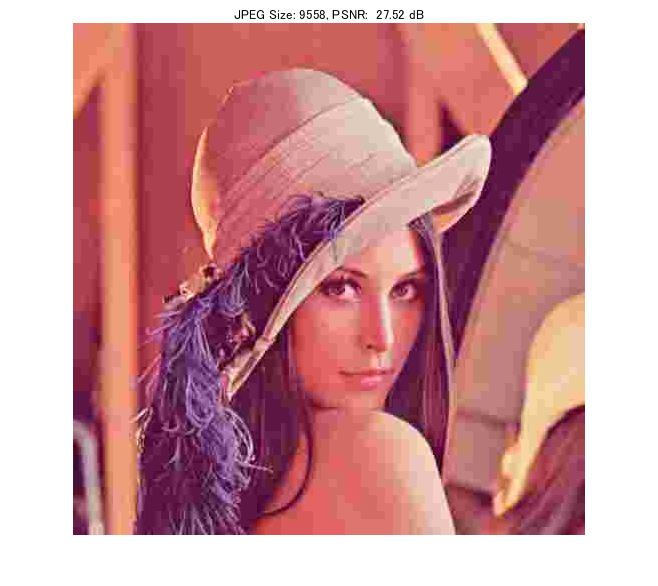

% Comparison
figure(8)
g = imread('lena.jpg');
imshow(g)
title(sprintf('JPEG Size: %d, PSNR: %6.2f dB',jpginfo.FileSize,psnr(im2uint8(u),g)))

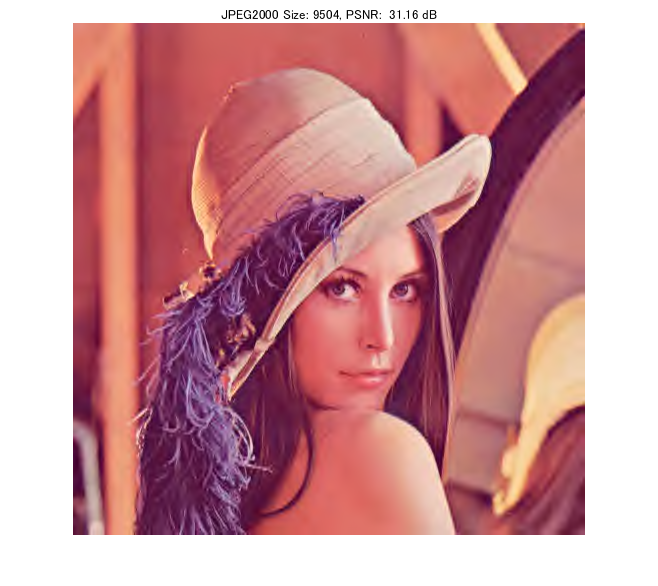

figure(9)
t = imread('lena.jp2');
imshow(t)
title(sprintf('JPEG2000 Size: %d, PSNR: %6.2f dB',jp2info.FileSize,psnr(im2uint8(u),t)))

### 関数定義

(Function definition)

Forward 9/7-transform w/ inplace implementation

function [subLL,subHL,subLH,subHH] = imtrans97(img)
%
% Copyright (C) 2005-2020 Shogo MURAMATSU, All rights reserved
%
alpha = -1.586134342059924;
beta  = -0.052980118572961;
gamma =  0.882911075530934;
delta =  0.443506852043971;
K =  1.230174104914001;

img = double(img);

% Vertical transform
img = inplaceprediction2(img,alpha);
img = inplaceupdate2(img,beta);
img = inplaceprediction2(img,gamma);
img = inplaceupdate2(img,delta);
img(1:2:end,:,:) = img(1:2:end,:,:)/K;
img(2:2:end,:,:) = img(2:2:end,:,:)*K;

% Horizontal transform
img = inplaceprediction2(permute(img,[2 1 3]),alpha);
img = inplaceupdate2(img,beta);
img = inplaceprediction2(img,gamma);
img = ipermute(inplaceupdate2(img,delta),[2 1 3]);
img(:,1:2:end,:) = img(:,1:2:end,:)/K;
img(:,2:2:end,:) = img(:,2:2:end,:)*K;

% Arrange coefficients
subLL = img(1:2:end,1:2:end,:);
subHL = img(1:2:end,2:2:end,:);
subLH = img(2:2:end,1:2:end,:);
subHH = img(2:2:end,2:2:end,:);

end

Inverse 9/7-transform w/ inplace implementation

function img = imitrans97(subLL,subHL,subLH,subHH)
%
% Copyright (C) 2005-2020 Shogo MURAMATSU, All rights reserved
%
alpha = -1.586134342059924;
beta  = -0.052980118572961;
gamma =  0.882911075530934;
delta =  0.443506852043971;
K =  1.230174104914001;

% Preparation of array
fullSize = (size(subLL) + size(subHH))./[1 1 2];
img = zeros(fullSize);

% Merge coefficients
img(1:2:end,1:2:end,:) = subLL;
img(1:2:end,2:2:end,:) = subHL;
img(2:2:end,1:2:end,:) = subLH;
img(2:2:end,2:2:end,:) = subHH;

% Horizontal transform
img(:,1:2:end,:) = img(:,1:2:end,:)*K;
img(:,2:2:end,:) = img(:,2:2:end,:)/K;
img = inplaceupdate2(permute(img,[2 1 3]),-delta);
img = inplaceprediction2(img,-gamma);
img = inplaceupdate2(img,-beta);
img = ipermute(inplaceprediction2(img,-alpha),[2 1 3]);

% Vertical transform
img(1:2:end,:,:) = img(1:2:end,:,:)*K;
img(2:2:end,:,:) = img(2:2:end,:,:)/K;
img = inplaceupdate2(img,-delta);
img = inplaceprediction2(img,-gamma);
img = inplaceupdate2(img,-beta);
img = inplaceprediction2(img,-alpha);

end

Prediction lifting step w/ inplace implementation

function picture = inplaceprediction2(picture,p)
%
% Copyright (C) 2005-2015 Shogo MURAMATSU, All rights reserved
%
if (mod(size(picture,1),2)==0)
    picture(2:2:end,:,:) = imlincomb(...
        p, picture(1:2:end,:,:), ...
        1, picture(2:2:end,:,:), ...
        p, [picture(3:2:end,:,:); picture(end-1,:,:)] ...
        );
else
    picture(2:2:end,:,:) = imlincomb(...
        p, picture(1:2:end-2,:,:), ...
        1, picture(2:2:end,:,:), ...
        p, picture(3:2:end,:,:) ...
        );    
end
end

Update lifting step w/ inplace implementation

function picture = inplaceupdate2(picture,u)
%
% Copyright (C) 2005-2020 Shogo MURAMATSU, All rights reserved
%
if (mod(size(picture,1),2)==0)
    picture(1:2:end,:,:) = imlincomb(...
        u, [picture(2,:,:); picture(2:2:end-1,:,:)], ... 
        1, picture(1:2:end,:,:), ...
        u, picture(2:2:end,:,:) ...
        );
else
    picture(1:2:end,:,:) = imlincomb(...
        u, [picture(2,:,:); picture(2:2:end-1,:,:)], ... 
        1, picture(1:2:end,:,:), ...
        u, [picture(2:2:end,:,:); picture(end-1,:,:)] ...
        );    
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.